1. Pentru $f(x)=e^x$¸si nodurile de interpolare $0,1,2$, aproximati $f(0.25)
$ prin interpolare Hermite si comparati rezultatul cu cel obtinut prin interpolare Lagrange. Dati o delimitare a erorii. Comparati cu rezultatul furnizat de software-ul utilizat.

x = [0 1 2];
f = exp(x);
df = exp(x);    

xx = [0.25];
yy = interpolareHermite(x, f, df, xx)

err = 0.0015

yy = 1.3130

yyL =LagrangeClassic(x,f,xx)

yyL = 1.1528

errL = abs(yy-yyL)

errL = 0.1602

yt = exp(xx)

yt = 1.2840

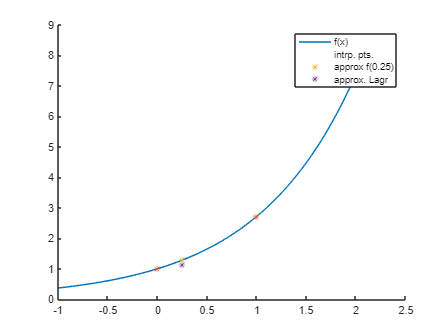


clf
hold on
t = linspace(-1,2.1);
plot(t, exp(t))
scatter(x,f,'marker','*')
scatter(xx,yy,'marker','*')
scatter(xx,yyL,'marker','*')
legend(["f(x)","intrp. pts.","approx f(0.25)","approx. Lagr"])
hold off

function [ res ] = interpolareHermite(x, f, fd, point )
% aproximeaza x folosind interpolarea Hermite
    % initializare
    [rows, m] = size(x);
    q = zeros(2 * m + 2, 2 * m + 2);
    z = zeros(2 * m + 2);
    
    % z contine x0 x0 x1 x1 x2 x2 ...
    % Q contine f(x0) f(x0) f(x1) x(x1) ...
    %           - f'(x0) f[x1,x0] f'(x1) f[x2,x1] ...
    for i = 1 : m
        % p2
        z(2 * i - 1) = x(i);
        z(2 * i) = x(i);
        q(2 * i - 1, 1) = f(i);
        q(2 * i, 1) = f(i);
        q(2 * i, 2) = fd(i);
        % p3
        if i ~= 1
            q(2*i-1,2)=(q(2*i-1,1)-q(2*i-2,1))/(z(2*i-1)-z(2*i-2));
        end
    end
    
    % se completeaza diferentele divizate
    for i = 3 : 2 * m
       for j = 3 : i
          q(i,j)=(q(i,j-1)-q(i-1,j-1))/(z(i)-z(i-j+1)); 
       end
    end    
        
    % calc p(i)
    n = size(point, 2);
    s = ones(1,n) * 1;
    p = ones(1,n) * q(1, 1);
    for i = 2 : 2 * m
       a = abs(x(floor(i/2)) - point);       
       s = s .* a;
       prev = p;
       p = p + s .* q(i,i);
       res = p; 
       err = abs(prev-p);
       if err<1e-5
          break 
       end
    end
    err
end

function u = LagrangeClassic(x,y,t)
    m = size(x,2);
    n = size(t,2);   
    pf = zeros('like', x);
    for k=1:m               
        pf = pf + (L(x,k) .* y(k));
    end      
    u = polyval(pf,t);
end

function lk = L(nodes,k)
    % polinomul fundamental L_k pentru nodurile nodes_1,...,nodes_n       
    % lk = prod_{j,j!=k}(x-xj)/prod_{j,j!=k}(xk-xj)
    m = size(nodes,2);
    roots = cat(2, nodes(1:k-1), nodes(k+1:m));    
    p = poly(roots);
    lk = p ./ polyval(p,nodes(k));
end